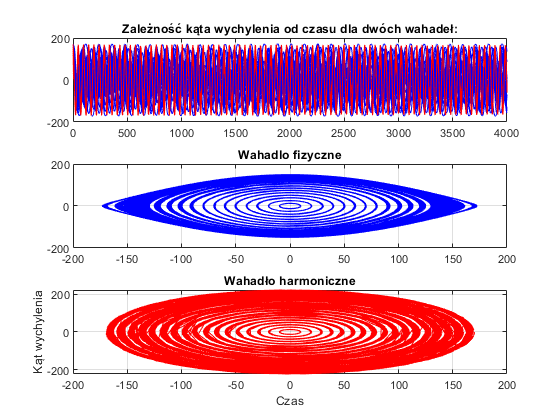

L = 10.0;
for alfa0 = 10:10:170
    [t,a] = ode113(@(t, a) fiz(t, a, L), [0, 4000], [alfa0, 0]);
    hold all;
    
    [t1,a1] = ode113(@(t, a) harm(t, a, L), [0, 4000], [alfa0, 0]);
    alfa = a(:,1);
    alfa1 = a1(:,1);
    v = a(:,2);
    v1 = a1(:,2);
    subplot(3,1,1)
    plot(t, alfa,'b', t1, alfa1,'r');
    title('Zależność kąta wychylenia od czasu dla dwóch wahadeł:')
    grid on;
    hold all;
    
    subplot(3,1,2);
    plot(alfa, v, 'b')
    title('Wahadlo fizyczne');
    grid on;
    hold all;
    
    subplot(3,1,3)
    plot(alfa1, v1, 'r'); 
    title('Wahadło harmoniczne');
end

grid on;
xlabel('Czas');
ylabel('Kąt wychylenia');

function dadt = fiz(t, a, L)
    g = 9.81;
    alfa = a(1);
    v = a(2);
    
    dalfadt = v / L;
    dvdt = - g * sind(alfa);
    
    dadt = zeros(2, 1);
    dadt(1) = dalfadt;
    dadt(2) = dvdt;
end

function dadt = harm(t, a, L)
    g = 9.81;
    alfa = a(1);
    v = a(2);    
    
    dalfadt = v / L;
    dvdt = - g * alfa * pi / 180.0;
    
    dadt = zeros(2, 1);
    dadt(1) = dalfadt;
    dadt(2) = dvdt;
end